# Transform Body Trajectory into Feet Trajectory

The previous script ([`animateLIPM`](matlab: edit animateLIPM)) creates the robot's center of mass (COM) trajectory and swing foot trajectories that are defined with respect to the world frame. All the position information is global. What we really want is the position information with respect to the robot's local body frame,. because in the end what we are moving are the two feet of the robot. Here we perform a transformation of reference frames to make the body and swing trajectories, which are defined with respect to the global origin, into feet trajectories with respect to the the body (COM). 

Another thing to note is the orientation of the feet. Here will make the robot walk while keeping orientation of the body normal to the ground. Therefore, the feet are always normal to the ground, too. Thus the transformation is done for the position only (orientation is added in the next section). You can change the yaw of the foothold to change the direction of robot walking. Also you can change rotate the body in pitch and roll direction during stance for more stability. For more information about hip strategy, check Benjamin Stephens' [Humanoid Push Recovery for Humanoid Robots with Force Controlled Joints](http://www.cs.cmu.edu/~cga/papers/stephens-hum10.pdf).

*Copyright 2019 The MathWorks, Inc.*

animateOn = false; 
% Load default parameters if previous script wasn't run
if ~exist('stepinfos','var')
    load('not_defaultstepinfos.mat')
end
footinfos = cell(size(stepinfos));

## Calculate Phase 1-1) Move the COM above one foot

This is the double stance phase. Because the two legs are working in harmony, the trajectory for both feet is simply copied with an offset equal to the torso width. 

idx = 1; 

% get bodypos wrt world from bodypos wrt foot 
newstate = stepinfos{idx}.state; % bodypos wrt foot
bodyposrel = [newstate(1,:); newstate(3,:); newstate(5,:)]; 
bodyposabs = bodyposrel + stepinfos{idx}.footplant; 

footinfos{idx}.timevec = stepinfos{idx}.timevec; 
% get footpos wrt body from bodypos wrt foot 
stancefootposrel = [-newstate(1,:); 
                     newstate(2,:);
                    -newstate(3,:);
                     newstate(4,:);
                    -newstate(5,:);
                     newstate(6,:)]; 
footinfos{idx}.footleft = stancefootposrel; 
footinfos{idx}.footright = stancefootposrel + [2*xTorso; 0; 0; 0; 0; 0];

size(footinfos{1}.timevec)

ans =      1   200


size(footinfos{1}.footleft)

ans =      6   200


## Calculate Phase 1-2) Make a half step

During this half-step phase, the robot moves the body while making half step. The underlying principle is simple: $\vec{\textrm{ac}} =\vec{\textrm{ab}} +\vec{\textrm{bc}}$ where 'ac' is the global position of the body (or swing foot), 'ab' is the global position of the foot hold (or body), and 'bc' is the relative position of the body w.r.t. foot hold (or swing foot w.r.t. body). 

**NOTE:** In this phase and other phases, we are creating the swing foot trajectory again. Remember earlier how we created a smooth trajectory for the swing foot after finding out consecutive position for one leg? That was created with respect to the world frame. Our robot doesn't necessarily have to follow that same swing trajectory. We just need to make sure it reaches the next foot hold and brings its foot above the ground to a certain height so that it doesn't drag. 

idx = 2; 

isLeftSupport = strcmp(stepinfos{idx}.mode, 'singlesupportleft'); 
isRightSupport = strcmp(stepinfos{idx}.mode, 'singlesupportright'); 
isDoubleSupport = strcmp(stepinfos{idx}.mode, 'doublesupport'); 

% get bodypos wrt world from bodypos wrt foot 
newstate = stepinfos{idx}.state; % bodypos wrt foot
bodyposrel = [newstate(1,:); newstate(3,:); newstate(5,:)]; 
bodyposabs = bodyposrel + stepinfos{idx}.footplant; 

footinfos{idx}.timevec = stepinfos{idx}.timevec; 
% get footpos wrt body from bodypos wrt foot 
stancefootposrel = [-newstate(1,:); 
                     newstate(2,:);
                    -newstate(3,:);
                     newstate(4,:);
                    -newstate(5,:);
                     newstate(6,:)]; 

% get footpos wrt body to use as waypoints   
swingabs = stepinfos{idx}.swing; 
footpos0 = swingabs(:,1) - bodyposabs(:,1);
footpos1 = swingabs(:,end) - bodyposabs(:,end);

% get trajectory from waypoints 
timestp0 = stepinfos{idx}.timevec(1); 
timestpf = stepinfos{idx}.timevec(end); 
[swingrel, dswingrel, ddswingrel] = getSwingFootTraj(footpos0, footpos1, swingHeight, timestp0, timestpf, Ts);     
swingpos = swingrel + bodyposabs; 
stepinfos{idx}.swingrel = swingrel; 

% save with [x; dx; y; dy; z; dz] format 
swingfootstate = [ swingrel(1,:); 
                  dswingrel(1,:); 
                   swingrel(2,:); 
                  dswingrel(2,:); 
                   swingrel(3,:); 
                  dswingrel(3,:)];    
              
if isLeftSupport
    footinfos{idx}.footright = swingfootstate; 
    footinfos{idx}.footleft  = stancefootposrel; 
elseif isRightSupport 
    footinfos{idx}.footleft  = swingfootstate; 
    footinfos{idx}.footright = stancefootposrel; 
else

end

size(footinfos{2}.timevec)

ans =      1    96


size(footinfos{2}.footleft)

ans =      6    96


## Calculate Phase 2) Consecutive Steps

This is the main part of the trajectory, but the underlying principle for converting the coordinate frames is the same. 

for idx = 3:length(stepinfos)
    % Check the support mode
    curMode = stepinfos{idx}.mode;
    isLeftSupport = strcmp(curMode, 'singlesupportleft'); 
    isRightSupport = strcmp(curMode, 'singlesupportright'); 
    isDoubleSupport = strcmp(curMode, 'doublesupport'); 
    
    footinfos{idx}.timevec = stepinfos{idx}.timevec; 
    % get bodypos wrt world from bodypos wrt foot 
    newstate = stepinfos{idx}.state; % bodypos wrt foot
    bodyposrel = [newstate(1,:); newstate(3,:); newstate(5,:)]; 
    bodyposabs = bodyposrel + stepinfos{idx}.footplant; 
    
    % get footpos wrt body from bodypos wrt foot 
    stancefootposrel = [-newstate(1,:); 
                         newstate(2,:);
                        -newstate(3,:);
                         newstate(4,:);
                        -newstate(5,:);
                         newstate(6,:)]; 
    
    % get footpos wrt body to use as waypoints   
    swingabs = stepinfos{idx}.swing; 
    footpos0 = swingabs(:,1) - bodyposabs(:,1);
    footpos1 = swingabs(:,end) - bodyposabs(:,end);
    
    % get trajectory from waypoints 
    timestp0 = stepinfos{idx}.timevec(1); 
    timestpf = stepinfos{idx}.timevec(end); 
    [swingrel, dswingrel, ddswingrel] = getSwingFootTraj(footpos0, footpos1, swingHeight, timestp0, timestpf, Ts);     
    swingpos = swingrel + bodyposabs; 
    stepinfos{idx}.swingrel = swingrel; 
    % save with [x; dx; y; dy; z; dz] format 
    swingfootstate = [ swingrel(1,:); 
                      dswingrel(1,:); 
                       swingrel(2,:); 
                      dswingrel(2,:); 
                       swingrel(3,:); 
                      dswingrel(3,:)];    
     
    % Assign the foot trajectory information based on which support mode the robot is in
    if isLeftSupport
        footinfos{idx}.footright = swingfootstate; 
        footinfos{idx}.footleft  = stancefootposrel; 
    elseif isRightSupport 
        footinfos{idx}.footleft  = swingfootstate; 
        footinfos{idx}.footright = stancefootposrel; 
    else
        
    end
end

## Animate the Foot Trajectory

Set up the plot

hFig = figure; 
hFig.Visible = 'on'; 
hFig.Units = 'Normalized'; 
hFig.OuterPosition = [0 0 1 1]; 
hAx2 = axes(hFig);
mcolors = get(gca, 'colororder'); 
stateL = footinfos{1}.footleft; 
stateR = footinfos{1}.footright;
hold on 
hLeftRel = plot3(stateL(1,1),stateL(3,1),stateL(5,1),'Color',mcolors(1,:)); 
hRightRel = plot3(stateR(1,1),stateR(3,1),stateR(5,1),'Color',mcolors(2,:));
hLeftPoint = plot3([0 stateL(1,1)],[0 stateL(3,1)],[0 stateL(5,1)], ...
                     '-o','LineWidth',2,'Color',mcolors(1,:),'MarkerIndices',2,'MarkerSize',8);
hRightPoint = plot3([0 stateR(1,1)],[0 stateR(3,1)],[0 stateR(5,1)], ...
                     '-o','LineWidth',2,'Color',mcolors(2,:),'MarkerIndices',2,'MarkerSize',8);
hold off 
view(3)
grid on
axis equal 
title('End Effector (Feet) Trajectory')
axis([-zRobot zRobot -zRobot zRobot -1.2*zRobot 0.2*zRobot])
legend('Left Foot Traj', 'Right Foot Traj', 'Left Foot', 'Right Foot',...
       'Location','northeast'); 

Animation loop

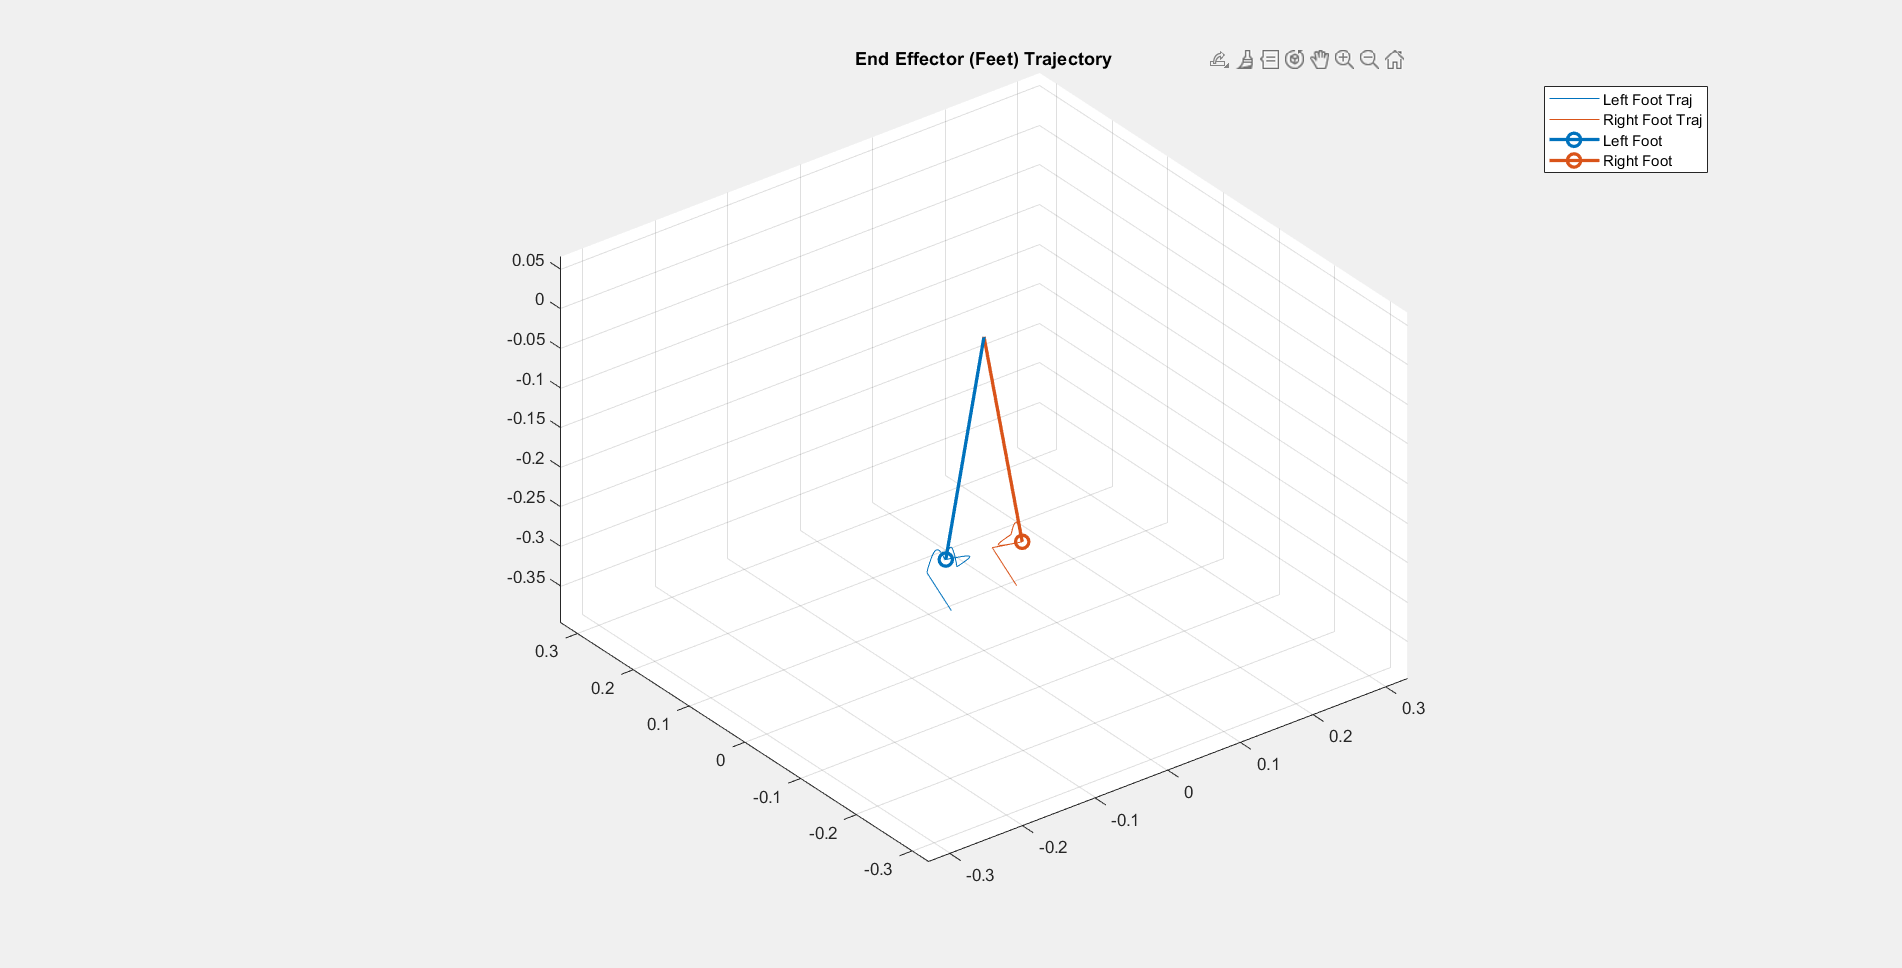

for footidx = 1:length(footinfos)
    stateL = footinfos{footidx}.footleft;
    stateR = footinfos{footidx}.footright; 
    for sidx = 1:size(stateL,2)
        appendLine(hLeftRel, stateL([1,3,5],sidx)); 
        appendLine(hRightRel, stateR([1,3,5],sidx)); 
        updateLine(hLeftPoint, [[0;0;0] stateL([1,3,5],sidx)]); 
        updateLine(hRightPoint, [[0;0;0] stateR([1,3,5],sidx)]); 
        if animateOn
            pause(0.005);
        end 
    end 
end

save('not_defaultfootinfos.mat', 'footinfos')

## Helper Functions  

Adds points to a graphics line object

function appendLine(gHandle, points)
    gHandle.XData(end+1) = points(1); 
    gHandle.YData(end+1) = points(2); 
    gHandle.ZData(end+1) = points(3); 
end 

Replaces points in a graphics line object

function updateLine(gHandle, points)
    gHandle.XData = points(1,:); 
    gHandle.YData = points(2,:); 
    gHandle.ZData = points(3,:); 
end